clc,clear
load('rx1_1_upsampled_lowpass.mat', ...
     'fd_up','fd_up_lp','td_new');
fd=fd_up_lp(:);
td=td_new(:);
fd=fd/(max(abs(fd)));
alpha = 0.145;
kappa = 19990000000;
Fm = 110000;
%alpha = 0.0001;
%kappa = 96999000000;
%Fm = 106000;
c1 = 1;
shift = 4.2;
BW = 2 * pi * Fm;

[tn, time_stamps, f_n, loc, NoF] = sampling_running_func_real(fd, td, alpha, kappa, Fm, c1, shift);

disp(['Number of Firings: ', num2str(NoF)]);

Number of Firings: 1856


NoF=length(time_stamps)-1;

iter=60;
F_est = reconstruction_running_func(NoF, td, f_n-shift, time_stamps, loc, tn, BW, Fm, iter);%%

k = 0;

% Right shift column 25
F_est(:,iter) = [zeros(k,1); F_est(1:end-k,iter)];

% Normalize
F_est(:,iter) = F_est(:,iter) / max(abs(F_est(:,iter)));



% Error metric
err = 10*log10( ...
    norm(fd(3500:end-5000) - F_est(3500:end-5000,iter))^2 / ...
    norm(fd(3500:end-5000))^2 )

err = -42.6838


%10 * log10( norm(fd(2000:end-1000) - F_est(2000:end-1000,iter))^2 )
disp(['Length of td: ', num2str(length(td))]);

Length of td: 204776


disp(['Length of fd: ', num2str(length(fd))]);

Length of fd: 204776


disp(['Size of F_est: ', mat2str(size(F_est))]);

Size of F_est: [204776 60]


disp(['iter: ', num2str(iter)]);

iter: 60


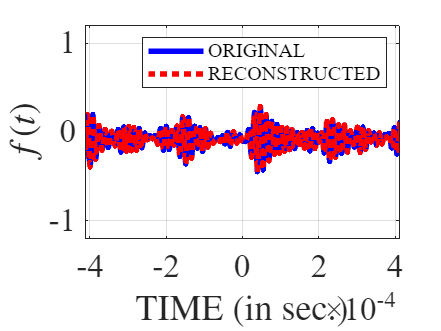



figure;
plot(td, (fd), 'b', 'DisplayName', 'ORIGINAL', 'LineWidth', 3); hold on;
plot(td, F_est(:,iter), 'r:', 'DisplayName', 'RECONSTRUCTED', 'LineWidth', 3); 

xlabel('TIME (in sec.)','FontSize',18,'FontName','Times','Interpreter','Latex');
ylabel('$f(t)$','FontSize',18,'FontName','Times','Interpreter','Latex');
set(gca,'FontSize',18,'FontName','Times');
legend('FontSize', 11);
grid on;
xlim([-0.00041, 0.00041]);  
ylim([-1.2, 1.2]);  

%exportgraphics(gcf, 'real_signal.pdf', 'ContentType', 'vector', 'BackgroundColor', 'none', 'Resolution', 300);


disp(abs(max(td)));

    0.0041



disp(pi*sqrt(alpha/kappa));

   8.4611e-06



disp(1/(2*Fm));

   4.5455e-06



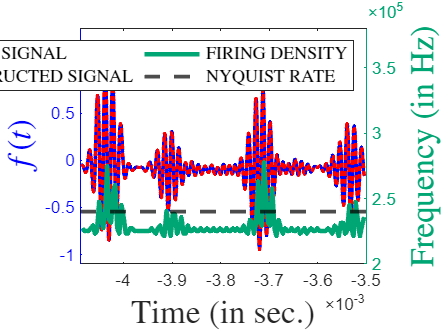

c1 = 1; c = c1;
% === Normalize the signal ===
normalized_fd = (fd ) / c;

% === Compute firing rate (density) as inverse of inter-spike intervals ===
firing_density = 1 ./ time_stamps;                % Instantaneous firing rate
firing_time = (tn(1:end-1) + tn(2:end)) / 2;  % Midpoints for firing

% === Compute derivative and related quantities ===
signal_derivative = gradient(normalized_fd, td);        
mod_signal_derivative = abs(signal_derivative);         
product_term = normalized_fd .* mod_signal_derivative;  

%% === Plot 1: Normalized Signal and Firing Density ===
figure;

% --- Left y-axis: Signal ---
yyaxis left
plot(td(200:end-190000), normalized_fd(200:end-190000), 'b', 'LineWidth', 2, 'DisplayName', 'ORIGINAL SIGNAL'); hold on;
plot(td(200:end-190000), F_est(200:end-190000,iter)/c1, 'r:', 'DisplayName', 'RECONSTRUCTED SIGNAL', 'LineWidth', 2); 
ylabel('$f(t)$', 'Interpreter', 'latex', 'FontSize', 18);

% Set left axis color to blue
ax = gca;
ax.YAxis(1).Color = [0 0 1];   % Blue

% --- Right y-axis: Firing Density ---
yyaxis right
plot(firing_time(2:end-1720), firing_density(2:end-1722),'Color', '[0 0.65 0.45]', 'LineWidth', 2.5, ...
    'DisplayName', 'FIRING DENSITY');
yline(240000, 'k--', 'LineWidth', 2, 'DisplayName', 'NYQUIST RATE');
ylabel('Frequency (in Hz)', 'Interpreter', 'latex', 'FontSize', 18);

% Set right axis color to magenta
ax.YAxis(2).Color = [0 0.65 0.45];   % Magenta

% --- Common axes formatting ---
yyaxis right
ylim([200000, 380000]);
yyaxis left
ylim([-1.1, 1.4]);

% --- Legend ---
legend('show', 'Interpreter', 'latex', 'FontSize', 10, 'Location', 'northeast', 'NumColumns', 2);

xlabel('Time (in sec.)', 'Interpreter', 'latex', 'FontSize', 18);
xlim([-0.004089, -0.0035]);
%set(gca, 'LooseInset', max(get(gca, 'TightInset'), 0.02))
% === Force clipping to axes (prevents extra lines in export) ===
ax = gca;
ax.XLimMode = 'manual';



%exportgraphics(gca, 'ultrasonic_proposed_2.pdf', ...
%    'ContentType', 'vector', ...
%    'BackgroundColor', 'none', ...
%    'Resolution', 300);
